# Main con un robot e 3 ostacoli

Initial configuration space (goal, obstacles, robot)

clear; close all;

grid = Grid(2,0,10);
G = [5,10]; grid.setGoal([5,10]);
X = grid.X; Y = grid.Y;

Obstacles and robot initial configuration

v1 = [1;0]; obstacles(1) = Obstacle(2.5,4,v1);
v2 = [-1;0];obstacles(2) = Obstacle(10,6,v2);
v3 = [0.5;-0.5]; obstacles(3) = Obstacle(2,10,v3);
n = length(obstacles);
r = Robot(5,1); 

SENSE

e = norm([r.xc,r.yc]-G); tsim = 0; tspan = 0.1;
r.setGrad(grid.agradX,grid.agradY);
while(e > 0.1 && tsim < 15)
    rx = r.xc; ry = r.yc; rtheta = r.theta;
    [detections,distances] = r.scan(obstacles,G,n);
    [distance,pos] = min(distances);
    dObstacle = obstacles(pos);
    detected = detections(pos);
    id = dObstacle.id;

PLAN

    if detected || r.obstacle.bypassed == false
        %switching to the bypassing potential from attractive or from bypassing of another obstacle
        if r.state == State.attractive || (detected == true && r.state == State.bypassing && id ~= r.obstacle.id)
            r.bypass(dObstacle,grid);
        else
            if norm([rx ry] - r.P1) < 0.1
                r.setGrad(r.gradXO,r.gradYO);
            end
            if norm([rx ry] - r.P2) < 0.1 %|| (~detected && id == r.obstacle.id)
                r.setGrad(grid.agradX,grid.agradY);
                r.state = State.attractive;
                r.obstacle.bypassed = true;
            end
        end
    end

Check for incorrect argument data type or missing argument in call to function 'coord2index'.

Error in Robot/bypass (line 175)
            j = coord2index(obj.P2);

ACT

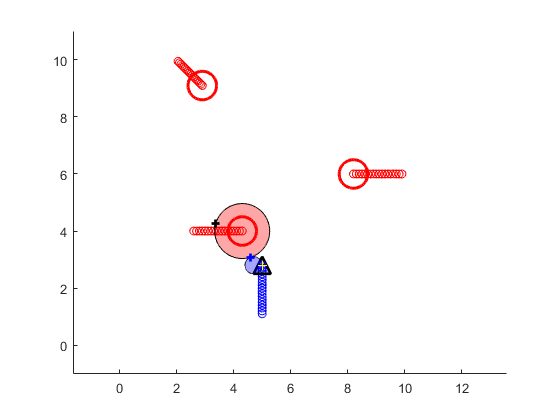

    if e <= 1 && r.state == State.attractive
        grid.setGrad((G(1)-X),(G(2)-Y));
    end
    r.move(tspan,grid);

    for k = 1:n
        obstacles(k).move(tspan);
    end
    e = norm([r.xc,r.yc]-G);
    tsim = tsim + tspan; pause(0);
end